# ACA CLASS ASSIGNMENT BY 26AE91R03

##  INITIALIZATION

clc; clear all;
% STATE SPACE MATRIX 
A = [-0.334   1.000;
     -2.52   -0.387];
% I/p Matrix
B = [-0.027;
     -2.6];

% Desired poles locations 

p = [-2.1 + 2.14i, ...
     -2.1 - 2.14i];

% Initial condition for the dynamical equation
x_0 = [ 5 ; 0 ];   % 5 deg AOA and 0 pitch)

T=10 ; % total time is 10s
dt=0.01;  
N= T/dt;
t=linspace(0,T,N+1);
x=zeros(2,N+1);

## Without any Controller design ( Free vibration response) 

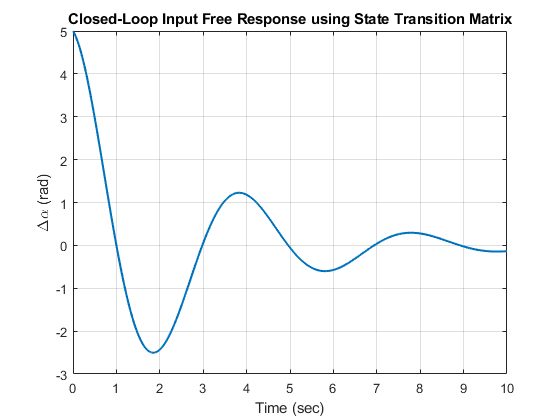

%Phi_1 = expm(A);
for j=1:N+1
x(:,j)= expm(A*t(j))*x_0;
end
AOAs_no_inp=x(1,:);
qs_no_inp = x(2,:);
figure;

plot(t,AOAs_no_inp,'LineWidth',1.8);

grid on;

xlabel('Time (sec)');
ylabel('\Delta\alpha (rad)');

title('Closed-Loop Input Free Response using State Transition Matrix');

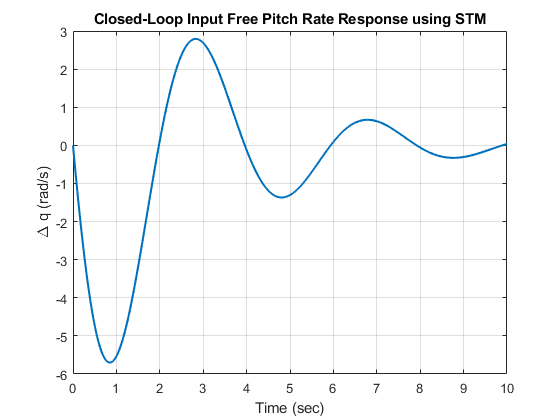

figure;

plot(t,qs_no_inp,'LineWidth',1.8);

grid on;

xlabel('Time (sec)');
ylabel('\Delta q (rad/s)');

title('Closed-Loop Input Free Pitch Rate Response using STM');

## Using ackerman's formulae


K = acker(A,B,p);

fprintf('Controller gain K1 =  %d, K2= %d \n',K(1),K(2))

Controller gain K1 =  -2.025027e+00, K2= -1.317048e+00 


% Now the CloseLoop system has become
A_acker= A-B*K;   % A tilda

for j=1:N+1
x(:,j)= expm(A_acker*t(j))*x_0;
end
AOAs_acker=x(1,:);
qs_acker = x(2,:);


## Plotting

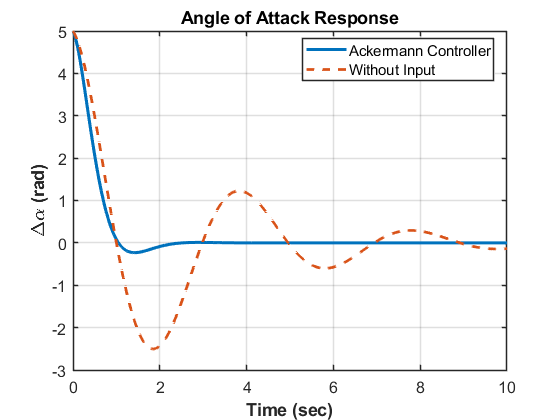


figure('Color','w');

plot(t, AOAs_acker, ...
    'LineWidth', 2.2, ...
    'LineStyle','-', ...
    'DisplayName','Ackermann Controller');

hold on;

plot(t, AOAs_no_inp, ...
    'LineWidth', 2.0, ...
    'LineStyle','--', ...
    'DisplayName','Without Input');

grid on;
box on;

xlabel('Time (sec)','FontSize',13,'FontWeight','bold');
ylabel('\Delta\alpha (rad)','FontSize',13,'FontWeight','bold');

title('Angle of Attack Response','FontSize',14,'FontWeight','bold');

legend('Location','best','FontSize',11);

set(gca,'FontSize',12,'LineWidth',1.1);

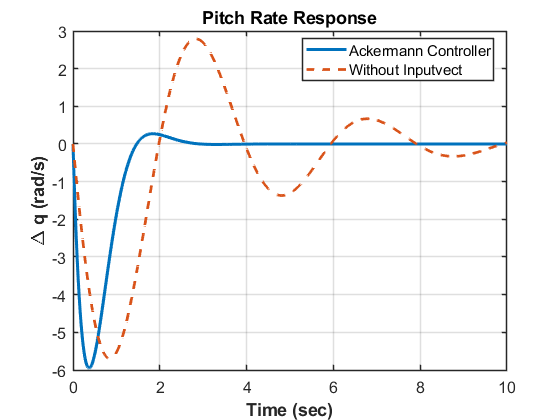


figure('Color','w');

plot(t, qs_acker, ...
    'LineWidth', 2.2, ...
    'LineStyle','-', ...
    'DisplayName','Ackermann Controller');

hold on;

plot(t, qs_no_inp, ...
    'LineWidth', 2.0, ...
    'LineStyle','--', ...
    'DisplayName','Without Inputvect');

grid on;
box on;

xlabel('Time (sec)','FontSize',13,'FontWeight','bold');
ylabel('\Delta q (rad/s)','FontSize',13,'FontWeight','bold');

title('Pitch Rate Response','FontSize',14,'FontWeight','bold');

legend('Location','best','FontSize',11);

set(gca,'FontSize',12,'LineWidth',1.1);

## Optimizing the Pole location by Hand

%% ============================================================
% 1. AIRCRAFT MODEL
% ============================================================

A = [-0.334   1.000;
     -2.52   -0.387];

B = [-0.027;
     -2.6];

%% ============================================================
% 2. INITIAL CONDITION
% ============================================================

alpha0 = 5*pi/180;       % 5 degree initial AOA
q0 = 0;

x0 = [alpha0;
      q0];

%% ============================================================
% 3. TIME VECTOR
% ============================================================

t = 0:0.01:8;

%% ============================================================
% 4. DIFFERENT DESIRED POLE LOCATIONS
% ============================================================

poles = [
    1+0.01i, 1-0.01i;
    0+0i, 0+0i;
    -1.5 + 1.5i, -1.5 - 1.5i;
    -2.1 + 2.14i, -2.1 - 2.14i;
    -2.5 + 2.5i, -2.5 - 2.5i;
    -3.0 + 3.0i, -3.0 - 3.0i;
    -4.0 + 4.0i, -4.0 - 4.0i
    -4.5 + 4.6i, -4.5 - 4.5i
    -5.0 + 5.0i, -5.0 - 5.0i
    -6.0 + 5.0i, -6.0 - 5.0i
];

nCases = size(poles,1);

%% ============================================================
% 5. STORAGE
% ============================================================

AOA = zeros(nCases,length(t));

q_response = zeros(nCases,length(t));

delta_e = zeros(nCases,length(t));

K_all = zeros(nCases,2);

%% ============================================================
% 6. LOOP THROUGH POLE LOCATIONS
% ============================================================

for i = 1:nCases

    %% Desired poles

    p = poles(i,:);

    %% Ackermann controller

    K = acker(A,B,p);

    K_all(i,:) = K;

    %% Closed-loop matrix

    Acl = A - B*K;

    %% State Transition Matrix response

    for k = 1:length(t)

        % State Transition Matrix
        Phi = expm(Acl*t(k));

        % Free response
        x = Phi*x0;

        % Store states
        AOA(i,k) = x(1);

        q_response(i,k) = x(2);

        % Elevator command
        delta_e(i,k) = -K*x;

    end

end

%% ============================================================
% 7. DISPLAY CONTROLLER GAINS
% ============================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf('             POLE LOCATION COMPARISON\n');

             POLE LOCATION COMPARISON


fprintf('============================================================\n');


for i = 1:nCases

    fprintf('\nCase %d\n',i);

    fprintf('Poles = %.3f + %.3fi , %.3f - %.3fi\n', ...
        real(poles(i,1)),imag(poles(i,1)), ...
        real(poles(i,2)),imag(poles(i,2)));

    fprintf('K1 = %.6f\n',K_all(i,1));

    fprintf('K2 = %.6f\n',K_all(i,2));

end


Case 1


Poles = 1.000 + 0.010i , 1.000 - -0.010i


K1 = 0.311878


K2 = 1.043300



Case 2


Poles = 0.000 + 0.000i , 0.000 - 0.000i


K1 = 0.932815


K2 = 0.267621



Case 3


Poles = -1.500 + 1.500i , -1.500 - -1.500i


K1 = -0.441635


K2 = -0.871952



Case 4


Poles = -2.100 + 2.140i , -2.100 - -2.140i


K1 = -2.025027


K2 = -1.317048



Case 5


Poles = -2.500 + 2.500i , -2.500 - -2.500i


K1 = -3.279432


K2 = -1.611714



Case 6


Poles = -3.000 + 3.000i , -3.000 - -3.000i


K1 = -5.274780


K2 = -1.975608



Case 7


Poles = -4.000 + 4.000i , -4.000 - -4.000i


K1 = -10.418374


K2 = -2.691425



Case 8


Poles = -4.500 + 4.600i , -4.500 - -4.500i


K1 = -13.739555


K2 = -3.041551



Case 9


Poles = -5.000 + 5.000i , -5.000 - -5.000i


K1 = -17.099165


K2 = -3.391278



Case 10


Poles = -6.000 + 5.000i , -6.000 - -5.000i


K1 = -21.089861


K2 = -4.119067


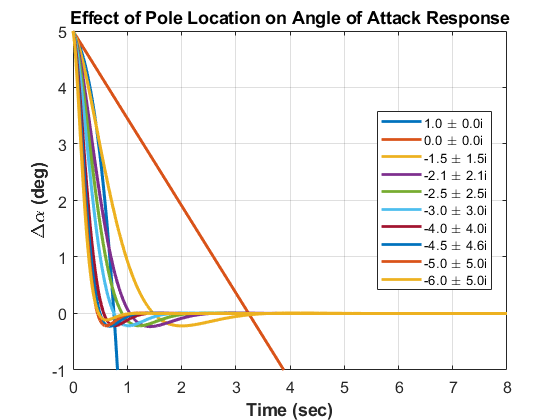


%% ============================================================
% 8. ANGLE OF ATTACK RESPONSE
% ============================================================

figure('Color','w');

hold on;

for i = 1:nCases

    plot(t,AOA(i,:)*180/pi, ...
        'LineWidth',2.0, ...
        'DisplayName', ...
        sprintf('%.1f \\pm %.1fi', ...
        real(poles(i,1)),abs(imag(poles(i,1)))));

end

grid on;
box on;

xlabel('Time (sec)', ...
    'FontSize',13, ...
    'FontWeight','bold');

ylabel('\Delta\alpha (deg)', ...
    'FontSize',13, ...
    'FontWeight','bold');

title('Effect of Pole Location on Angle of Attack Response', ...
    'FontSize',14, ...
    'FontWeight','bold');

legend('Location','best', ...
    'FontSize',10);

set(gca,'FontSize',12);
ylim([-1,5 ...
    ]);